
samples.names = {...

    'K1794';...
    'K1795';...
    'K1796'...

    };
samples.current = {...
    
    [3.979E-6,2.221E-6];...
    [5.61893e-006,3.1215e-006];...
    [1.0023e-005,5.57e-006]...

    };
samples.rho = {...

    [.8503,.85];...
    [0.607947,0.615908];...
    [0.378186,0.380604]...    

    };
samples.n = {...

    [1.867e+15,5.406E15];...
    [1.70367e+016,1.83407e+016];...
    [8.01712e+016,5.47317e+016]...


    };
samples.mu = {...
    
    [15.911,8.495];...
    [4.89331,4.63982];...
    [1.86319,2.91289]...

    };

Plotte einfach mal Ladungsträgerkonzentration gegen Mobilität

PLOT = [];
for i = 2:3
    x = samples.mu{i};
    y = samples.rho{i};
    
    PLOT = [PLOT;[x',y']];
end
PLOT = sortrows(PLOT)

PLOT =     1.8632    0.3782
    2.9129    0.3806
    4.6398    0.6159
    4.8933    0.6079


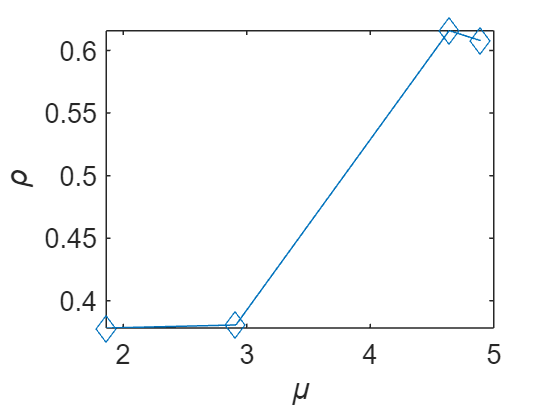

plot(PLOT(:,1),PLOT(:,2),'d-')
xlabel('\mu')
ylabel('\rho')